% Charger les solutions depuis le fichier
load('solutionsfiltree.mat');

disp(solutions_filtrees);

    1.0000   19.1690  -77.3055   87.7756   -3.0769  -26.3387    9.0000    0.0000
    1.0000   36.3243  -65.3505   87.8578  -81.3645    2.8398    9.0000    0.0000
    1.0000   30.1983  -65.5659   71.1200   -7.4389  -72.2084    9.0000   -0.0000
    1.0000  -68.9275   57.8828   49.3235  -11.8443  -17.4699    9.0000    0.0000
    1.0000   13.5457  -66.4648   89.0803   -2.5319  -44.0820    9.0000   -0.0000
    1.0000  -63.7331   49.9477   56.0555  -12.0026  -25.8223    9.0000    0.0000
    1.0000    6.5695  -59.5624   88.0381    2.7357  -43.7177    9.0000   -0.0000
    2.0000  -19.9806   59.8825    6.8208  -53.1410  -39.1718    8.9391    1.0448
    2.0000   62.2134  -56.9500   26.4821  -50.7553  -25.4403    8.9391    1.0448
    2.0000   42.3948  -89.4715   85.9069  -17.4995  -23.8629    8.9391    1.0448
    2.0000  -43.1281   58.8884  -17.2837   -5.7876   79.5758    8.9391    1.0448
    2.0000   57.8855  -52.0837   27.8955  -49.4998  -33.5460    8.9391    1.0448
    2.0000   36.0218  -86.26

### Variation de theta pour chaque solution. Tous les points avec le même numéro de point auront la même couleur dans le graphique

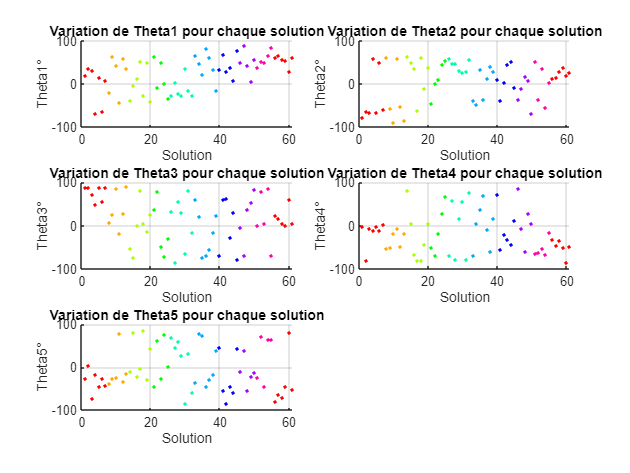

figure;
unique_colors_map = containers.Map('KeyType', 'double', 'ValueType', 'double');
color_index = 1;

for i = 1:size(solutions_filtrees, 1)
    point_number = solutions_filtrees(i, 1);
    if ~isKey(unique_colors_map, point_number)
        unique_colors_map(point_number) = color_index;
        color_index = color_index + 1;
    end
end

% Définir le nombre de lignes et de colonnes pour la grille
num_rows = 3; % Modifier le nombre de lignes selon le nombre de joints
num_cols = 2; % Nombre de colonnes pour afficher les graphiques

for joint = 1:5
    % Définir la position du subplot dans la grille
    subplot(num_rows, num_cols, joint);
    
    % Boucle sur chaque solution
    for i = 1:size(solutions_filtrees, 1)
        point_number = solutions_filtrees(i, 1); % Numéro de point
        color_index = unique_colors_map(point_number); % Récupérer l'index de couleur pour ce numéro de point

        % Définir la couleur en fonction de l'index récupéré
        color = hsv2rgb([(color_index-1)/(size(unique_colors_map, 1)-1), 1, 1]); % Utiliser l'espace colorimétrique HSV pour obtenir des couleurs distinctes

        % Tracer le point avec la couleur définie
        scatter(i, solutions_filtrees(i, joint+1), 5, color, 'filled'); % Vous pouvez ajuster la taille du point (50) selon vos préférences
        hold on;
    end

    % Titre et étiquettes des axes
    title(['Variation de Theta', num2str(joint), ' pour chaque solution']);
    xlabel('Solution');
    ylabel(['Theta', num2str(joint), '°']);
    grid on;
end

### Variation de theta pour chaque solution avec une couleur pour chaque point de la trajectoire a suivre puis une forme pour chaque theta

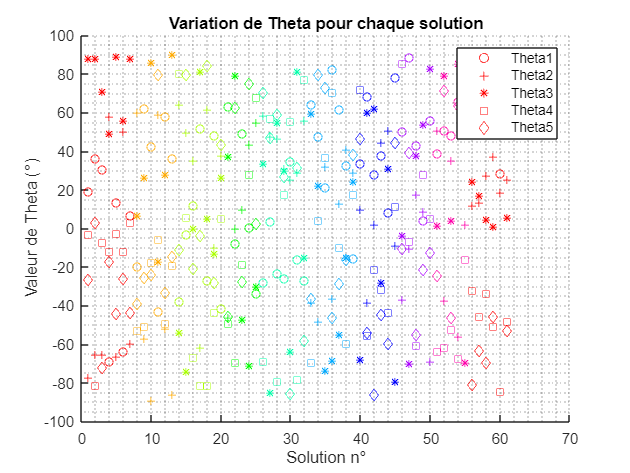

% Créer un tableau de hachage pour mapper chaque numéro de point à une couleur
unique_colors_map = containers.Map('KeyType', 'double', 'ValueType', 'double');
color_index = 1;

for i = 1:size(solutions_filtrees, 1)
    point_number = solutions_filtrees(i, 1); % Numéro de point
    if ~isKey(unique_colors_map, point_number)
        unique_colors_map(point_number) = color_index; % Assigner une nouvelle couleur pour chaque nouveau numéro de point
        color_index = color_index + 1;
    end
end

% Convertir les angles en degrés et ajuster les angles à l'intervalle [-180, 180]
solutions_filtrees_deg = solutions_filtrees(:, 2:6);

% Créer une nouvelle figure
figure;

% Boucle sur chaque solution
for i = 1:size(solutions_filtrees, 1)
    point_number = solutions_filtrees(i, 1); % Numéro de point
    
    % Récupérer l'index de couleur pour ce numéro de point
    color_index = unique_colors_map(point_number);

    % Définir la couleur en fonction de l'index récupéré
    color = hsv2rgb([(color_index-1)/(size(unique_colors_map, 1)-1), 1, 1]);

    % Tracer le point avec la couleur définie et une forme différente pour chaque valeur de theta
    for joint = 1:5
        % Choisir la forme de marqueur en fonction de la valeur de theta
        switch joint
            case 1
                marker = 'o';
            case 2
                marker = '+';
            case 3
                marker = '*';
            case 4
                marker = 's';
            case 5
                marker = 'd';
        end

        % Tracer le point avec la couleur définie et la forme de marqueur appropriée
        scatter(i, solutions_filtrees_deg(i, joint), 30, color, marker);
        hold on;
    end
end

% Titre et étiquettes des axes
title('Variation de Theta pour chaque solution');
xlabel('Solution n°');
ylabel('Valeur de Theta (°)');

% Légende
legend('Theta1', 'Theta2', 'Theta3', 'Theta4', 'Theta5');

% Afficher la grille
grid minor;

### Position pour chaque articulation, une couleur par point de la trajectoire

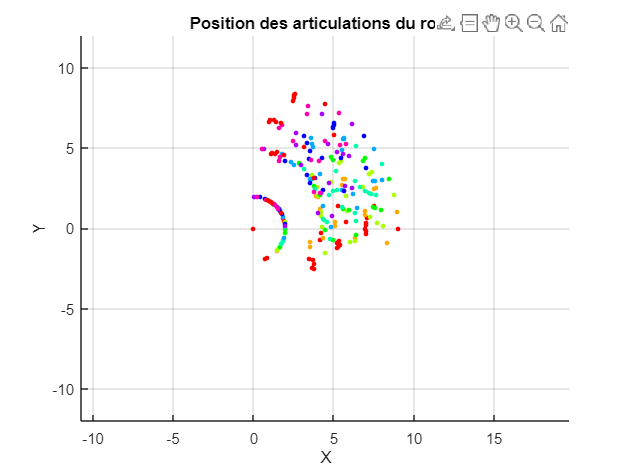


% Créer un tableau de hachage pour mapper chaque numéro de point à une couleur
unique_colors_map = containers.Map('KeyType', 'double', 'ValueType', 'double');
color_index = 1;

for i = 1:size(solutions_filtrees, 1)
    point_number = solutions_filtrees(i, 1); % Numéro de point
    if ~isKey(unique_colors_map, point_number)
        unique_colors_map(point_number) = color_index; % Assigner une nouvelle couleur pour chaque nouveau numéro de point
        color_index = color_index + 1;
    end
end

% Créer une nouvelle figure
figure;

hold on; % Garder le graphique actif pour ajouter les données de chaque solution

% Visualisation des configurations du robot
for i = 1:size(solutions_filtrees, 1)
    % Extraire les angles d'articulation pour cette configuration
    theta1 = solutions_filtrees(i, 2);
    theta2 = solutions_filtrees(i, 3);
    theta3 = solutions_filtrees(i, 4);
    theta4 = solutions_filtrees(i, 5);
    theta5 = solutions_filtrees(i, 6);

    % Calcul des positions des articulations du robot avec les valeurs des angles d'articulation calculées
    O = [0, 0]; % Position de l'origine
    A = [a1*cosd(theta1), a1*sind(theta1)]; % Position de l'articulation A
    B = A + [a2*cosd(theta1+theta2), a2*sind(theta1+theta2)]; % Position de l'articulation B
    C = B + [a3*cosd(theta1+theta2+theta3), a3*sind(theta1+theta2+theta3)]; % Position de l'articulation C (extrémité de l'effecteur)
    D = C + [a4*cosd(theta1+theta2+theta3+theta4), a4*sind(theta1+theta2+theta3+theta4)]; % Position de l'articulation C (extrémité de l'effecteur)
    E = D + [a5*cosd(theta1+theta2+theta3+theta4+theta5), a5*sind(theta1+theta2+theta3+theta4+theta5)]; % Position de l'articulation C (extrémité de l'effecteur)

    % Récupérer l'index de couleur pour ce numéro de point
    color_index = unique_colors_map(solutions_filtrees(i, 1));

    % Définir la couleur en fonction de l'index récupéré
    color = hsv2rgb([(color_index-1)/(size(unique_colors_map, 1)-1), 1, 1]);

    % Tracer le robot pour cette configuration 
    scatter([O(1), A(1), B(1), C(1), D(1), E(1)], [O(2), A(2), B(2), C(2), D(2), E(2)], 10, color, 'filled'); % Marques pour les articulations
end 
grid on;

% Calculer les limites des axes
xlim([-12, 12]); 
ylim([-12, 12]);
axis equal

% Configurer le titre et les étiquettes des axes
title('Position des articulations du robot');
xlabel('X');
ylabel('Y');

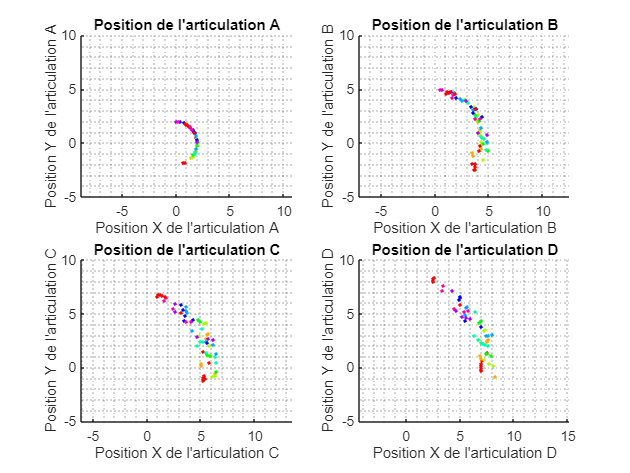




% Créer un graphique distinct pour chaque articulation
figure;

% Créer un tableau de hachage pour mapper chaque numéro de point à une couleur
unique_colors_map = containers.Map('KeyType', 'double', 'ValueType', 'double');
color_index = 1;

for i = 1:size(solutions_filtrees, 1)
    point_number = solutions_filtrees(i, 1); % Numéro de point
    if ~isKey(unique_colors_map, point_number)
        unique_colors_map(point_number) = color_index; % Assigner une couleur pour chaque nouveau numéro de point
        color_index = color_index + 1;
    end
end

% Articulation A
subplot(2, 2, 1);
title('Position de l''articulation A');
xlabel('Position X de l''articulation A');
ylabel('Position Y de l''articulation A');
hold on;
% Calculer les positions de l'articulation A pour chaque solution
A_positions = zeros(size(solutions_filtrees, 1), 2);
for i = 1:size(solutions_filtrees, 1)
    % Extraire les angles d'articulation pour cette configuration
    theta1 = solutions_filtrees(i, 2);
    
    % Calculer la position de l'articulation A pour cette solution
    A = [a1*cosd(theta1), a1*sind(theta1)]; % Position de l'articulation A
    A_positions(i, :) = A;
    
    % Récupérer l'index de couleur pour ce numéro de point
    color_index = unique_colors_map(solutions_filtrees(i, 1));

    % Définir la couleur en fonction de l'index récupéré
    color = hsv2rgb([(color_index-1)/(size(unique_colors_map, 1)-1), 1, 1]);

    % Tracer le point avec la couleur définie
    scatter(A(1), A(2), 5, color, 'filled');
end
grid minor;
xlim([-5, 5]); % Définir les limites des axes X
ylim([-5, 10]); % Définir les limites des axes Y

% Articulation B
subplot(2, 2, 2);
title('Position de l''articulation B');
xlabel('Position X de l''articulation B');
ylabel('Position Y de l''articulation B');
hold on;
% Calculer les positions de l'articulation B pour chaque solution
B_positions = zeros(size(solutions_filtrees, 1), 2);
for i = 1:size(solutions_filtrees, 1)
    % Extraire les angles d'articulation pour cette configuration
    theta1 = solutions_filtrees(i, 2);
    theta2 = solutions_filtrees(i, 3);
    
    % Calculer la position de l'articulation B pour cette solution
    B = A_positions(i, :) + [a2*cosd(theta1+theta2), a2*sind(theta1+theta2)]; % Position de l'articulation B
    B_positions(i, :) = B;
    
    % Récupérer l'index de couleur pour ce numéro de point
    color_index = unique_colors_map(solutions_filtrees(i, 1));

    % Définir la couleur en fonction de l'index récupéré
    color = hsv2rgb([(color_index-1)/(size(unique_colors_map, 1)-1), 1, 1]);

    % Tracer le point avec la couleur définie
    scatter(B(1), B(2), 5, color, 'filled');
end
grid minor;
xlim([-5, 5]); % Définir les limites des axes X
ylim([-5, 10]); % Définir les limites des axes Y

% Articulation C
subplot(2, 2, 3);
title('Position de l''articulation C');
xlabel('Position X de l''articulation C');
ylabel('Position Y de l''articulation C');
hold on;
% Calculer les positions de l'articulation C pour chaque solution
C_positions = zeros(size(solutions_filtrees, 1), 2);
for i = 1:size(solutions_filtrees, 1)
    % Extraire les angles d'articulation pour cette configuration
    theta1 = solutions_filtrees(i, 2);
    theta2 = solutions_filtrees(i, 3);
    theta3 = solutions_filtrees(i, 4);
    
    % Calculer la position de l'articulation C pour cette solution
    C = B_positions(i, :) + [a3*cosd(theta1+theta2+theta3), a3*sind(theta1+theta2+theta3)]; % Position de l'articulation C
    C_positions(i, :) = C;
    
    % Récupérer l'index de couleur pour ce numéro de point
    color_index = unique_colors_map(solutions_filtrees(i, 1));

    % Définir la couleur en fonction de l'index récupéré
    color = hsv2rgb([(color_index-1)/(size(unique_colors_map, 1)-1), 1, 1]);

    % Tracer le point avec la couleur définie
    scatter(C(1), C(2), 5, color, 'filled');
end
grid minor;
xlim([-5, 5]); % Définir les limites des axes X
ylim([-5, 10]); % Définir les limites des axes Y

% Articulation D
subplot(2, 2, 4);
title('Position de l''articulation D');
xlabel('Position X de l''articulation D');
ylabel('Position Y de l''articulation D');
hold on;
% Calculer les positions de l'articulation D pour chaque solution
D_positions = zeros(size(solutions_filtrees, 1), 2);
for i = 1:size(solutions_filtrees, 1)
    % Extraire les angles d'articulation pour cette configuration
    theta1 = solutions_filtrees(i, 2);
    theta2 = solutions_filtrees(i, 3);
    theta3 = solutions_filtrees(i, 4);
    theta4 = solutions_filtrees(i, 5);
    
    % Calculer la position de l'articulation D pour cette solution
    D = C_positions(i, :) + [a4*cosd(theta1+theta2+theta3+theta4), a4*sind(theta1+theta2+theta3+theta4)]; % Position de l'articulation D
    D_positions(i, :) = D;
    
    % Récupérer l'index de couleur pour ce numéro de point
    color_index = unique_colors_map(solutions_filtrees(i, 1));

    % Définir la couleur en fonction de l'index récupéré
    color = hsv2rgb([(color_index-1)/(size(unique_colors_map, 1)-1), 1, 1]);

    % Tracer le point avec la couleur définie
    scatter(D(1), D(2), 5, color, 'filled');
end
grid minor;
xlim([-5, 5]); % Définir les limites des axes X
ylim([-5, 10]); % Définir les limites des axes Y

% Réglage des espacements entre les sous-graphiques
subplot(2, 2, 1); axis equal; 
subplot(2, 2, 2); axis equal; 
subplot(2, 2, 3); axis equal; 
subplot(2, 2, 4); axis equal;